Aby to fungovalo, musí se přidat cesta, zároveň zavedeme nápovědu (stačí spustit na začátku relace jednou)

addpath(genpath('C:\Fyzing\Baka\MATLAB\MNPBEM17'));

run('C:\Fyzing\Baka\MATLAB\MNPBEM17/makemnpbemhelp.m')

Removing existing index directory at C:\Fyzing\Baka\MATLAB\MNPBEM17\help\helpsearch-v4_en
Process Duration: 0.001192
Successfully created search database.


clc 
clear all
close all

Set up the dielectric environment:

%  options for BEM simulation
opstat = bemoptions( 'sim', 'stat' );
%  table of dielectric functions
epstab = { epsconst( 1),  epsdrude('myAg') };  %epstable( 'silver.dat' ) };

epsconst(1) ... dielectrc function of vacuum

p1 = trirod( 10, 30, [ 20, 10, 20 ] );
p1 = rot(p1, 90, [0,1,0])

p1 = particle : 
     verts: [694×3 double]
     faces: [703×4 double]
    interp: 'flat'


p1 = shift( p1, [ 0, 10 ,7.5 ] );

p2 = trirod( 10, 30, [ 20, 10, 20 ] );
p2 = rot(p2, 90, [1,0,0])

p2 = particle : 
     verts: [694×3 double]
     faces: [703×4 double]
    interp: 'flat'


p2 = shift( p2, [ 10, 0, -7.5 ] );

n1 for the circumference of the rod, n2 for the polar angles of the rod caps, n3 for the cylinder-shaped middle part of the rod, and

p = comparticle( epstab, { p1, p2 }, [ 2, 1; 2, 1 ], 1, 2, opstat );

clf
plot( p, 'FaceColor', [1,1,1] );
xlim("auto")
ylim("auto")
zlim("auto")
view([0 90])
%view([90 0])
%view([-45 10.2])
%plot( p, 'EdgeColor', "b");
% plot( p, 'EdgeColor', 'b', 'nvec', 1 );

%  set up BEM solver
% bem = bemsolver( p, op );
% [ ene, ur] = plasmonmode( p, 10 )

nev = 20
bemeig = bemstateig(p, opstat, 'nev', nev);
% from the eigensolution, we can get the corresponding pseudocharges on the
% surface corresponding to different eigenmodes
eigencharges = bemeig.ur
eigenpseudolambdas = bemeig.ene %unit matrix with eigeneenrgies on diagonal
pfacepos = p.pos
pfacearea = p.area

writematrix(eigencharges,"MY_PROJECTS\baka01\eigencharges.csv")
writematrix(eigenpseudolambdas,"MY_PROJECTS\baka01\eigenpseudolambdas.csv")
writematrix(pfacepos,"MY_PROJECTS\baka01\pfacepos.csv")
writematrix(pfacearea,"MY_PROJECTS\baka01\pfacearea.csv")

plot(p, eigencharges(:,3))

xlim("auto")
ylim("auto")
zlim("auto")
view([-45.7 8.8])


plot(p, eigencharges(:,4))

xlim("auto")
ylim("auto")
zlim("auto")
view([-45.7 8.8])

## EELS to find the right prefactor

%  width of electron beam and electron velocity
[ width, vel ] = deal( 0.3, 0.446 * 2.99792458e8 );
%  impact parameters 
[X, Y] = meshgrid(linspace(-40,40,70),linspace(-40,40,70));
imp = [ X(:) , Y(:) ]; %linspace( -30, 30, 32 );
%  loss energies in eV
ene = [ 2.764490219193807885e+00, 2.961953806279079782e+00 ]

ene =     2.7645    2.9620


%ene = linspace(2,4,21)
% ene = [4.2,  4.5] * 1e15 * 1.05457182e-34 / 1.602e-19 ; %linspace( 2.5, 4.5, 60 );


%  convert energies to nm
units;  enei = eV2nm ./ ene;

## Quasistatic

%%  BEM solution
%  BEM solver
bem = bemsolver( p, opstat );
%  electron beam excitation
exc = electronbeam( p, imp, width, vel, opstat );
%  surface and bulk losses
[ psurf, pbulk ] = deal( zeros( numel( imp(:,1) ), numel( enei ) ) );

multiWaitbar( 'BEM solver', 0, 'Color', 'g', 'CanCancel', 'on' );
%  loop over wavelengths
for ien = 1 : length( enei )
  %  surface charges
  sig = bem \ exc( enei( ien ) );
  %  EELS losses
  [ psurf( :, ien ), pbulk( :, ien ) ] = exc.loss( sig );
  
  multiWaitbar( 'BEM solver', ien / numel( enei ) );
end
%  close waitbar
multiWaitbar( 'CloseAll' );

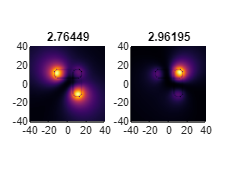

%%  final plot
%  electron energy loss probability
figure()
for i = 1:2
    subplot(1,2,i);
    pc = pcolor(X, Y, reshape(psurf(:,i) , size(X)) );
    pc.EdgeAlpha=0;
    colormap inferno;
    title(ene(i));
    axis square;

end

##     Retarded

%%  BEM solution
%  BEM solver
opret =  bemoptions( 'sim', 'ret', 'interp', 'curv' );
bem = bemsolver( p, opret );
%  electron beam excitation
exc = electronbeam( p, imp, width, vel, opret );
%  surface and bulk losses
[ psurf, pbulk ] = deal( zeros( numel( imp(:,1) ), numel( enei ) ) );

multiWaitbar( 'BEM solver', 0, 'Color', 'g', 'CanCancel', 'on' );
%  loop over wavelengths
for ien = 1 : length( enei )
  %  surface charges
  sig = bem \ exc( enei( ien ) );
  %  EELS losses
  [ psurf( :, ien ), pbulk( :, ien ) ] = exc.loss( sig );
  
  multiWaitbar( 'BEM solver', ien / numel( enei ) );
end
%  close waitbar
multiWaitbar( 'CloseAll' );

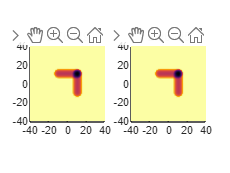

%%  final plot
%  electron energy loss probability
figure()
for i = 1:2
    subplot(1,2,i);
    pc = pcolor(X, Y, reshape(psurf(:,i) , size(X)) );
    pc.EdgeAlpha=0;
    colormap inferno;
    title(ene(i));
    axis square;

end

## Comparison of quasistatic and retarded calculation in spectra for a few points

For particles with following parameters 

We get different spectra using quasistatic /  retarded calculations

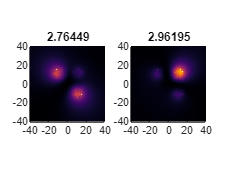 / 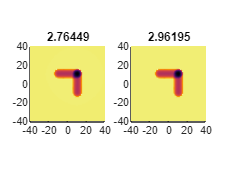

We will thus map the "full" spectra in a few points: 

%%  width of electron beam and electron velocity
[ width, vel ] = deal( 0.3, 0.446 * 2.99792458e8 );
%%  impact parameters 
imp =  [[0,0],
        [15,15],
        [15,-20]]

imp =      0     0
    15    15
    15   -20


%% loss energies in eV
% ene = [ 2.764490219193807885e+00, 2.961953806279079782e+00 ]
ene = linspace(0.2,4,50)

ene =     0.2000    0.2776    0.3551    0.4327    0.5102    0.5878    0.6653    0.7429    0.8204    0.8980    0.9755    1.0531    1.1306    1.2082    1.2857    1.3633    1.4408    1.5184    1.5959    1.6735    1.7510    1.8286    1.9061    1.9837    2.0612    2.1388    2.2163    2.2939    2.3714    2.4490    2.5265    2.6041    2.6816    2.7592    2.8367    2.9143    2.9918    3.0694    3.1469    3.2245    3.3020    3.3796    3.4571    3.5347    3.6122    3.6898    3.7673    3.8449    3.9224    4.0000


% ene = [4.2,  4.5] * 1e15 * 1.05457182e-34 / 1.602e-19 ; %linspace( 2.5, 4.5, 60 );

%  convert energies to nm
units;  enei = eV2nm ./ ene;

%% Quasistatic BEM solution
%  BEM solver
bem = bemsolver( p, opstat );
%  electron beam excitation
exc = electronbeam( p, imp, width, vel, opstat );
%  surface and bulk losses
[ psurfq, pbulkq ] = deal( zeros( numel( imp(:,1) ), numel( enei ) ) );

multiWaitbar( 'BEM solver', 0, 'Color', 'g', 'CanCancel', 'on' );
%  loop over wavelengths
for ien = 1 : length( enei )
  %  surface charges
  sig = bem \ exc( enei( ien ) );
  %  EELS losses
  [ psurfq( :, ien ), pbulkq( :, ien ) ] = exc.loss( sig );
  
  multiWaitbar( 'BEM solver', ien / numel( enei ) );
end
%  close waitbar
multiWaitbar( 'CloseAll' );

%% retarded BEM solution
%  BEM solver
opret =  bemoptions( 'sim', 'ret', 'interp', 'curv' );
bem = bemsolver( p, opret );
%  electron beam excitation
exc = electronbeam( p, imp, width, vel, opret );
%  surface and bulk losses
[ psurfr, pbulkr ] = deal( zeros( numel( imp(:,1) ), numel( enei ) ) );

multiWaitbar( 'BEM solver', 0, 'Color', 'g', 'CanCancel', 'on' );
%  loop over wavelengths
for ien = 1 : length( enei )
  %  surface charges
  sig = bem \ exc( enei( ien ) );
  %  EELS losses
  [ psurfr( :, ien ), pbulkr( :, ien ) ] = exc.loss( sig );
  
  multiWaitbar( 'BEM solver', ien / numel( enei ) );
end
%  close waitbar
multiWaitbar( 'CloseAll' );

Plotting the spectra:

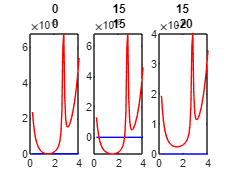

clf
figure()
for iimp = 1:length(imp)
    subplot(1,length(imp),iimp)
    plot(ene, psurfq(iimp,:),"Color",[0 0 1])
    hold on
    plot(ene, psurfr(iimp,:),"Color",[1 0 0])
    title(imp(iimp,:))
end

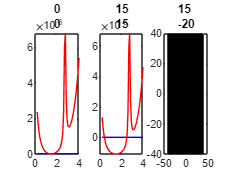

pcolor(X, Y, reshape(psurf(:,i) , size(X)) )

imagesc( ene, imp, psurf + pbulk );  hold on

Error using image
Image XData and YData must be vectors.

Error in imagesc (line 52)
    hh = image(varargin{:}, 'CDataMapping', 'scaled');


set( gca, 'YDir', 'norm' );
colorbar

xlabel( 'Loss energy (eV)' );
ylabel( 'x (nm)' );

title( 'Loss probability (eV^{-1})' );
                         